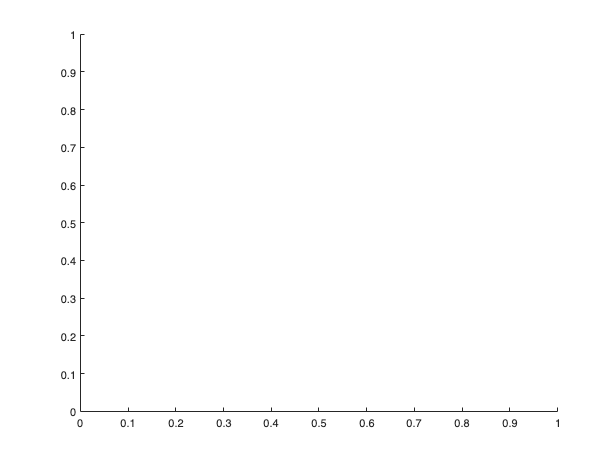

%%%% Author: Anson Li
%%%% Email: ting.h.li@mail.mcgill.ca
close all; clf; clc; cla;

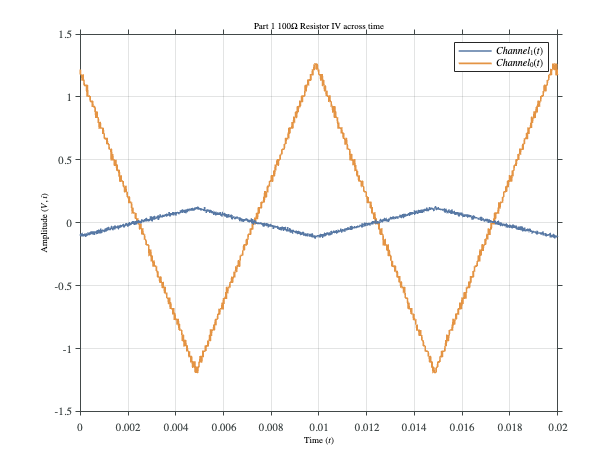

working_directory = './';
input_csv_filename = '1-TRIANGLE-100-OHMS-WAVE.csv';



% output file name computations
output_pdf_filename = [input_csv_filename(1:end - 4), '.pdf'];
output_png_filename = [input_csv_filename(1:end-4),'-plotted.png'];

%read data from csv
data=readmatrix(strcat(working_directory,input_csv_filename));
% standard oscilloscope time step
dt = 8*10^(-6); 

% plotting
figure;
hold on;
dataLength=size(data,1);
t = 0:dt:(dataLength-1)*dt;

% grab the channels 
% remark: the green channel on osc. is channel0 here, while the blue
% channel on osc is channel1
channel0 = data(:, 4); channel1 = data(:,8);

% sometimes we want to do calculations with the channels, so we plot
% signal0, 1 instead of channel 0,1
signal0=channel0; signal1 = channel1./10;
% channel labels customization
signal0Label = ['v_{x}(t)']; signal1Label = ['i_{r}(t)'];
% subplot(1,2,1);
hold on;
plot(t, channel0, 'DisplayName', ['${Channel}_0(t)$']);
plot(t, channel1, 'DisplayName', ['${Channel}_1(t)$']);
title(['Part 1 ', '$100\Omega$', ' Resistor IV across time'], 'interpreter', 'latex');
legend('Interpreter', 'latex');

xlabel('Time ($t$)', 'Interpreter', 'latex');
ylabel('Amplitude ($V,i$)', 'Interpreter', 'latex');
grid on;

%%%%%
%%%%%
%%%%%

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
hold off;

% print(gcf, strcat(working_directory,output_pdf_filename), '-vector', '-dpdf', '-bestfit');
% saveas(gcf, strcat(working_directory,output_png_filename));
% figure;
% hold on;
